data = readtable('Salary Data.csv');  

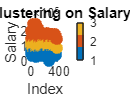


numeric_data = data{:, 'Salary'};

data_size = size(numeric_data, 1);
indices = 1:data_size;  

num_clusters = min(3, data_size);  
[idx, centroids] = kmeans(numeric_data, num_clusters);

figure;
scatter(indices, numeric_data, 50, idx, 'filled');  
title('K-Means Clustering on Salary Data');
xlabel('Index');  
ylabel('Salary');  
colormap(lines(num_clusters));  
colorbar('Ticks', 1:num_clusters, 'TickLabels', cellstr(num2str((1:num_clusters)')));